# Projekt 1

## Algorytmy

Generowanie podzbiorów:

%UWAGA, proszę nie zmieniać tego wektora (ilość dźwięków w skali to 7)
Z = [1, 2, 3, 4, 5, 6, 7];

przyklad = [1, 2, 3, 5];

o = zeros(size(Z)) + [przyklad zeros(1, length(Z)-length(przyklad))]; %dopełnienie zerami
podzbiory(Z, o, 10); 

     1     2     3     5

     1     2     3     5     7

     1     2     3     5     6

     1     2     3     5     6     7

     1     2     3     4

     1     2     3     4     7

     1     2     3     4     6

     1     2     3     4     6     7

     1     2     3     4     5

     1     2     3     4     5     7



%Z - zbiór główny
%A - kolejne generowane podzbiory
%p - ilość generowanych podzbiorów

Podzbiory k-elementowe (parametr pierwszy odpowiada w późniejszym zagadnieniu za liczbę akordów):

kelementowy = k_elementowy(4, Z, 21)

kelementowy =      1     2     3     4
     1     2     3     5
     1     2     4     5
     1     3     4     5
     2     3     4     5
     1     2     3     6
     1     2     4     6
     1     3     4     6
     2     3     4     6
     1     2     5     6


%k - ilość elementów w podzbiorze
%p - ilość generowanych podzbiorów
%Z - zbiór główny
niezerowe = any(kelementowy, 2);
kelementowy = kelementowy(niezerowe, :)

kelementowy =      1     2     3     4
     1     2     3     5
     1     2     4     5
     1     3     4     5
     2     3     4     5
     1     2     3     6
     1     2     4     6
     1     3     4     6
     2     3     4     6
     1     2     5     6


Wygenerowanie losowego podzbior k-elementowego  zbioru Z:

losowy_wiersz_kel = kelementowy(randi(size(kelementowy,1)), :)

losowy_wiersz_kel =      1     3     4     7


Permutacje:

X = [4, 5, 6, 3, 2, 1];
%max(x) = n - najwiekszy element zbioru
%p = 10 - ilość generowanych permutacji ze zbioru X
%X - zbiór główny
permutacje(max(X),10,X)

ans =      4     6     1     2     3     5
     4     6     1     2     5     3
     4     6     1     3     2     5
     4     6     1     3     5     2
     4     6     1     5     2     3
     4     6     1     5     3     2
     4     6     2     1     3     5
     4     6     2     1     5     3
     4     6     2     3     1     5
     4     6     2     3     5     1


mutacje = permutacje(size(losowy_wiersz_kel, 2), factorial(size(losowy_wiersz_kel,2)), losowy_wiersz_kel);

ilosc = 24

koniec


niezerowe = any(mutacje, 2);
mutacje = mutacje(niezerowe, :);

Wygenerowanie losowej permutacji podzbioru k-elementowego ze zbioru Z:

losowy_wiersz_mutant = mutacje(randi(size(mutacje,1)), :)

losowy_wiersz_mutant =      7     4     1     3


## Generowanie akordów i ich progresji

Tonacja i majmin są zmiennymi edytowanymi przez użytkownika, pozwalają na wybranie dowolnej tonacji:

tonacja = "F";
majmin = "min";
A = 110;
notes = struct("C", -9, "CSharp", -8, ...
    "D", -7, "DSharp", -6, ...
    "E", -5, "F", -4, ... 
    "FSharp", -3, "G", -2, ...
    "GSharp", -1, "A", 0, ...
    "ASharp", 1, "B", 2);
notes.(tonacja);
majorScaleNotesRelations = [0, 2, 4, 5, 7, 9, 11];
minorScaleNotesRelations = [0, 2, 3, 5, 7, 8, 10];

%tworzenie macierzy triad akordów w skali i ich nazw
majorChordCreate = [[0 4 7]; [0 3 7]; [0 3 7]; [0 4 7]; [0 4 7]; [0 3 7]; [0 3 6]];
minorChordCreate = [[0 3 7]; [0 3 6]; [0 4 7]; [0 3 7]; [0 3 7]; [0 4 7]; [0 4 7]];
majorChordCreateNames = ["maj"; "min"; "min"; "maj"; "maj"; "min"; "dim"];
minorChordCreateNames = ["min"; "dim"; "maj"; "min"; "min"; "maj"; "maj"];

akordy = losowy_wiersz_mutant;

progresja = zeros(size(akordy,2), 3);
l = 1:size(akordy,1);
%nazwy akordów: inicjalizacja
chords_in_progression = string(zeros(size(progresja, 1), 1)');

Generowanie częstotliwości triad dla j-tego akord zadanej tonacji:

for j = akordy
    j
    for i = 1:size(minorChordCreate, 2)
            if majmin == "maj"
                SNR = majorScaleNotesRelations(j);
                CC = majorChordCreate(j, i);
            elseif majmin == "min"
                SNR = minorScaleNotesRelations(j);
                CC = minorChordCreate(j, i);
            end
        frequency = A*2^((SNR + notes.(tonacja) + CC)/12)
        progresja(l, i) = frequency;
        
    end
    %nazwy akordów przypisanie dla skal major, minor
    if majmin == "maj"
        chords_in_progression(l) = chords_in_progression(l) + majorChordCreateNames(j);
    else
        chords_in_progression(l) = chords_in_progression(l) + minorChordCreateNames(j);
    end
    l = l + 1;
end

j = 7

frequency = 155.5635

frequency = 195.9977

frequency = 233.0819

j = 4

frequency = 116.5409

frequency = 138.5913

frequency = 174.6141

j = 1

frequency = 87.3071

frequency = 103.8262

frequency = 130.8128

j = 3

frequency = 103.8262

frequency = 130.8128

frequency = 155.5635

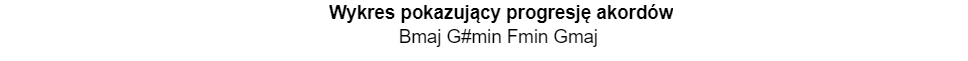

%usuwam zera z chords_in_progression (zainicjalizowane jako zeros)
chords_in_progression = erase(chords_in_progression, '0');

%pobranie kluczy ze struktury notes i zamienienie ich na stringi
all_notes = string(fieldnames(notes)');

%znalezienie pozycji nuty we wszystkich nutach
gdzie_nuta = find(all_notes==tonacja);

%zapętlenie wychodzących poza zakres nut za pomocą modulo 12 
% (nuty powtarzają się okresowo)
akordy = akordy + gdzie_nuta - 1;
akordy(akordy>12) = mod(akordy(akordy>12), 12);

%połączenie nut z rodzajami akordów i zamiana słowa Sharp na oznaczenie #
chords_in_progression = all_notes(akordy) + chords_in_progression;
chords_in_progression = replace(chords_in_progression, "Sharp", "#");

%wykres pokazujący progresję
figure('Position', [100, 100, 1600, 100]);
text(0.5, 0.5, sprintf('%s ', chords_in_progression{:}), 'FontSize', 14, 'HorizontalAlignment', 'center');
title("Wykres pokazujący progresję akordów", FontSize=14)
axis off;

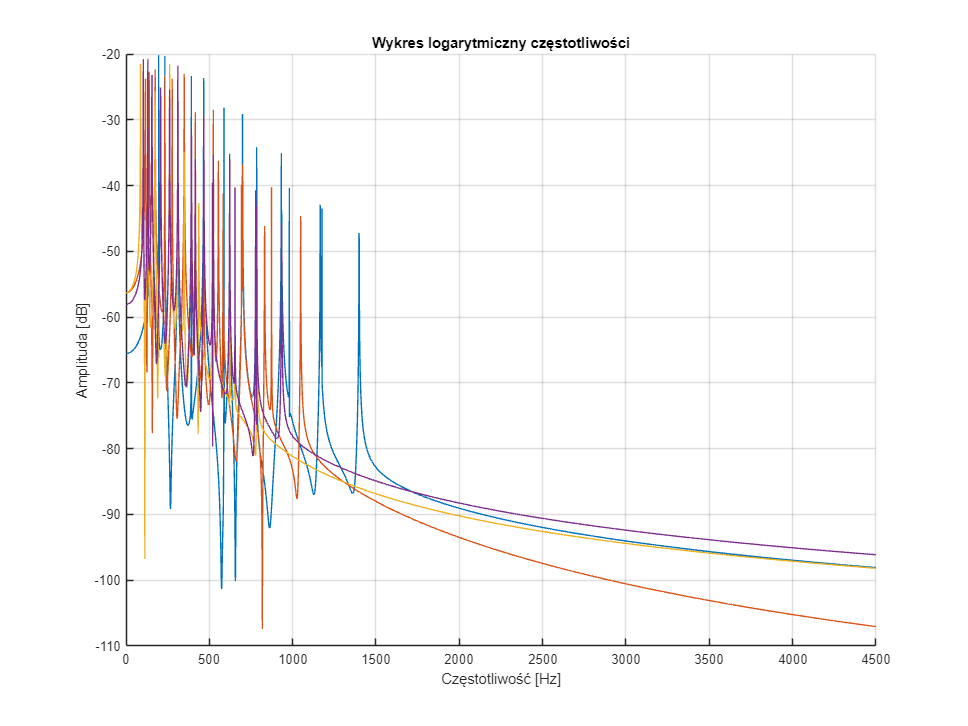

GeneratorDzwieku(progresja)

Kody m-plików użytych w tym projekcie:

Funkcja generująca k-elementowy pozdbiór zbioru n-elementowego Z:

Funkcja generujące permutacje:

Funkcja generująca dźwięk akordu i wykres logarytmiczny częstotliowości od natężenia dźwięku:

Funkcja nie wykorzystana w naszym projekcie to generowanie wszystkich podzbiorów zbioru Z: